# 离散卷积

clc
clear
close all

[u1,n] = stepseq(0,-5,50);
u2 = stepseq(10,-5,50);

%input
x = u1 - u2;
%系统函数
h = (0.9.^n) .* u1;
%离散卷积output
y = conv(x,h);

%绘图
subplot(3,1,1);
stem(n,x,'filled');
title('输入序列');
xlabel('n');
ylabel('x(n)');
%限制坐标轴的范围
axis([-5 50 0 1.5]);

subplot(3,1,2);
stem(n,h,'filled');
title('冲击响应序列');
xlabel('n');
ylabel('h(n)');
axis([-5 50 0 1.5]);

subplot(3,1,3);
%离散卷积的长度为两者长度和-1
n1 = (n(1)+n(1):n(length(x))+n(length(h)));

n1 =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39


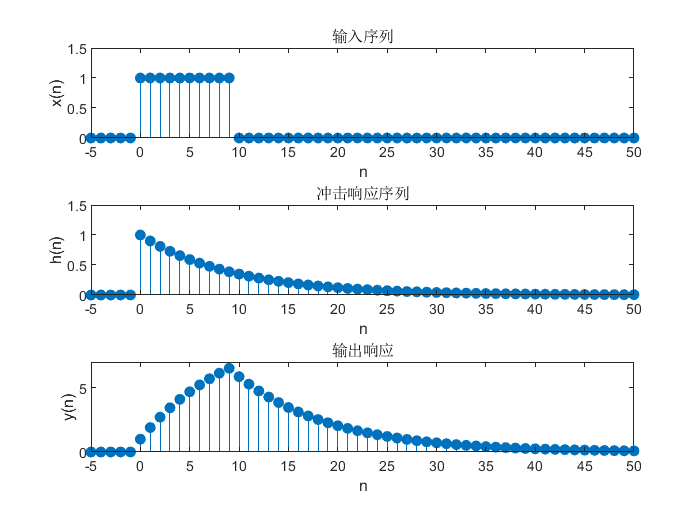

stem(n1,y,'filled');
title('输出响应');
xlabel('n');
ylabel('y(n)');
axis([-5,50,0,7]);

function[x,n]=stepseq(n0,n1,n2)
n=(n1:n2);
x=((n-n0)>=0);
end
%离散阶跃序列